% Wrapper Script for the Phase Diagram generator 

readcsvUC = true;  % if set to false you justnned to change the values in this wrapper script 

% = = = = = USER DEFINED VARIABLES = = = = = 
userCom.composition = 'UNH';
userCom.filename = 'data_ternaryUNH-RF.csv';
userCom.num_elements = 3;
userCom.non_CH_data = 'targets_extra-cols.csv'; %points that will not impact the convex hull but will appear on the plot (ie data model may have been trained on)
userCom.non_CH_data_label = 'OQMD training data';
userCom.plotTitle = [userCom.composition,' Ternary Phase Diagram'];
userCom.delta_E_metastable = 0.1;
userCom.show_change_of_basis = 0;
% = = = = = = = = = = = = = = = = = = = = = =

addpath functions\
tic
% cleaning data
clean = data_cleaning(userCom.filename,char(userCom.composition));

%filename = userCom.non_CH_data;

% reading suplimentary data
if ~isnumeric(userCom.non_CH_data)
    non_CH_data = read_suplementary_data(userCom.non_CH_data,userCom.composition);
    [stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(non_CH_data,userCom.composition,0,0);
    non_CH_results.spid = stable_pahse_ids;
    non_CH_results.mspid = metastable_phase_ids;
    non_CH_results.u = u;
    non_CH_results.v = v;
    non_CH_results.k = k;
    disp(' ')
end

22 convex hull nodes identified
0 metastable phases found on first pass
17 planes removed
7 stable-phases and 0 metastable-phases identified after trimming to lower covex hull


%%
[stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(clean,userCom.composition,userCom.delta_E_metastable,userCom.show_change_of_basis);

36 convex hull nodes identified
50 metastable phases found on first pass
19 planes removed
15 stable-phases and 42 metastable-phases identified after trimming to lower covex hull


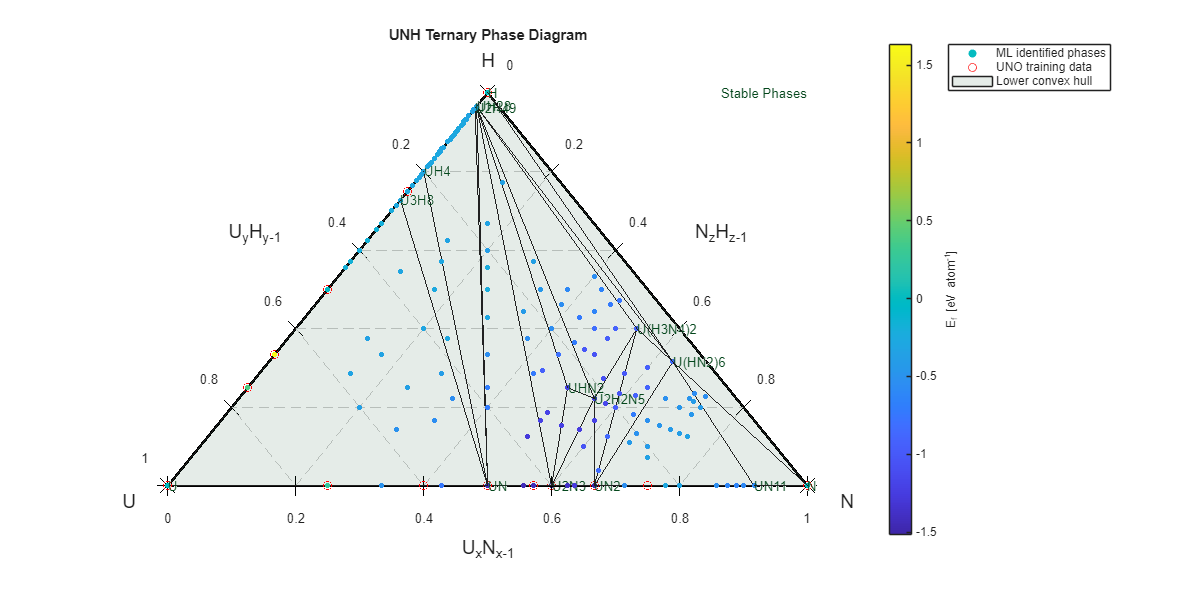

Stable Phases identified:
                      Ef_eV       
                __________________

    U(H3N4)2    -0.906000590326598
    U(HN2)6     -0.830610847634653
    U2H2N5       -1.23715770097098
    U2H49       -0.338136373330789
    U2N3          -1.5127065652061
    U3H8        -0.278038151283667
    UH28        -0.338136373330789
    UH4         -0.297113458226355
    UHN2         -1.20556953487839
    UN           -1.41583815017175
    UN11        -0.581471771523425
    UN2            -1.495191535229
    U                            0
    N                            0
    H                            0

Metastable Phases identified:
                      Ef_eV       
      

results.spid = stable_pahse_ids;
results.mspid = metastable_phase_ids;
results.u = u;
results.v = v;
results.k = k;

% need to fix learning type error and graph labeling as axes are in the
% wrng order and still hardcoded at UNO

ternary_stable_phase_plotting(clean,results,non_CH_results,non_CH_data,userCom.composition,...
                                  0,... 3d view 
                                  1,... vu-vec
                                  1, ... stab.ph
                                  userCom.plotTitle ...
                                  )

toc

Elapsed time is 1.905887 seconds.


% = = = = = USER DEFINED VARIABLES = = = = = 
userCom.composition = 'UNO';
userCom.filename = 'data_ternaryUNO-RF.csv';
userCom.num_elements = 3;
userCom.non_CH_data = 'targets_extra-cols.csv'; %points that will not impact the convex hull but will appear on the plot (ie data model may have been trained on)
userCom.non_CH_data_label = 'OQMD training data';
userCom.plotTitle = [userCom.composition,' Ternary Phase Diagram'];
userCom.delta_E_metastable = 0.1;
userCom.show_change_of_basis = 0;
% = = = = = = = = = = = = = = = = = = = = = =

addpath functions\
tic
% cleaning data
clean = data_cleaning(userCom.filename,char(userCom.composition));

filename = userCom.non_CH_data;

% reading suplimentary data
if ~isnumeric(userCom.non_CH_data)
    non_CH_data = read_suplementary_data(userCom.non_CH_data,userCom.composition);
    [stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(non_CH_data,userCom.composition,0,0);
    non_CH_results.spid = stable_pahse_ids;
    non_CH_results.mspid = metastable_phase_ids;
    non_CH_results.u = u;
    non_CH_results.v = v;
    non_CH_results.k = k;
    disp(' ')
end

24 convex hull nodes identified
0 metastable phases found on first pass
17 planes removed
9 stable-phases and 0 metastable-phases identified after trimming to lower covex hull


%%
[stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(clean,userCom.composition,userCom.delta_E_metastable,userCom.show_change_of_basis);

34 convex hull nodes identified
13 metastable phases found on first pass
23 planes removed
11 stable-phases and 13 metastable-phases identified after trimming to lower covex hull


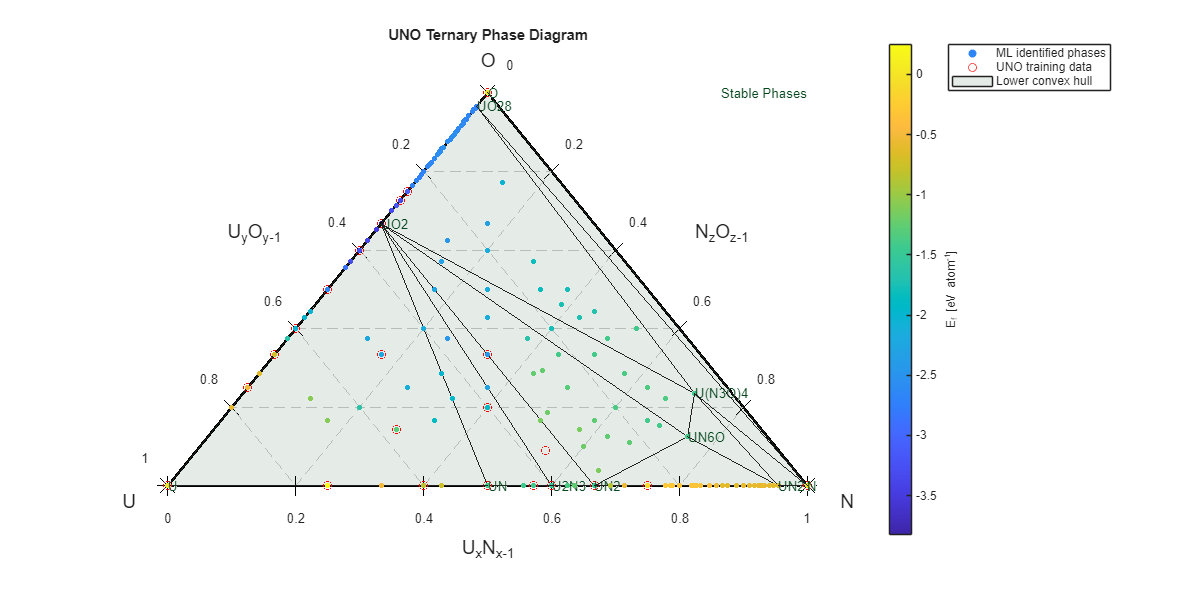

Stable Phases identified:
                     Ef_eV       
               __________________

    U(N3O)4     -1.42715634875806
    U2N3         -1.5127065652061
    UN          -1.41583815017175
    UN2           -1.495191535229
    UN21       -0.595715781183339
    UN6O        -1.40799515100765
    UO2          -3.8192987939272
    UO28        -2.68346612173728
    U                           0
    N                           0
    O                           0

Metastable Phases identified:
                    Ef_eV       
              __________________

    U2NO       -2.12388278231483
    U2O49      -2.68346612173728
    U3N2O      -1.87353355686194
    U3N3O2 

results.spid = stable_pahse_ids;
results.mspid = metastable_phase_ids;
results.u = u;
results.v = v;
results.k = k;

% need to fix learning type error and graph labeling as axes are in the
% wrng order and still hardcoded at UNO

ternary_stable_phase_plotting(clean,results,non_CH_results,non_CH_data,userCom.composition,...
                                  0,... 3d view 
                                  1,... vu-vec
                                  1, ... stab.ph
                                  userCom.plotTitle ...
                                  )

toc

Elapsed time is 1.783145 seconds.


% = = = = = USER DEFINED VARIABLES = = = = = 
userCom.composition = 'UNO';
userCom.filename = 'data_ternaryUNO-NN.csv';
userCom.num_elements = 3;
userCom.non_CH_data = 'targets_extra-cols.csv'; %points that will not impact the convex hull but will appear on the plot (ie data model may have been trained on)
userCom.non_CH_data_label = 'OQMD training data';
userCom.plotTitle = [userCom.composition,' Ternary Phase Diagram'];
userCom.delta_E_metastable = 0.1;
userCom.show_change_of_basis = 0;
% = = = = = = = = = = = = = = = = = = = = = =

addpath functions\
tic
% cleaning data
clean = data_cleaning(userCom.filename,char(userCom.composition));

% reading suplimentary data
if ~isnumeric(userCom.non_CH_data)
    non_CH_data = read_suplementary_data(userCom.non_CH_data,userCom.composition);
    [stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(non_CH_data,userCom.composition,0,0);
    non_CH_results.spid = stable_pahse_ids;
    non_CH_results.mspid = metastable_phase_ids;
    non_CH_results.u = u;
    non_CH_results.v = v;
    non_CH_results.k = k;
    disp(' ')
end

24 convex hull nodes identified
0 metastable phases found on first pass
17 planes removed
9 stable-phases and 0 metastable-phases identified after trimming to lower covex hull


%%
[stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(clean,userCom.composition,userCom.delta_E_metastable,userCom.show_change_of_basis);

36 convex hull nodes identified
41 metastable phases found on first pass
24 planes removed
14 stable-phases and 33 metastable-phases identified after trimming to lower covex hull


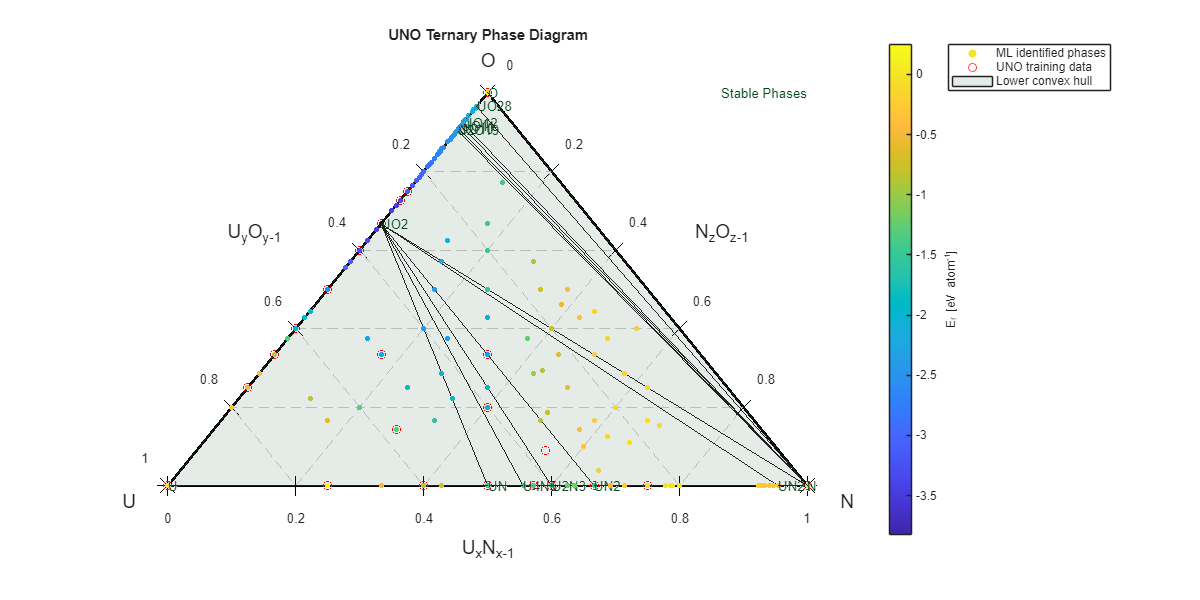

Stable Phases identified:
                   Ef_eV       
             __________________

    U2N3       -1.5127065652061
    U2O19     -2.43653410421165
    U4N5      -1.47879773831711
    UN        -1.41583815017175
    UN2         -1.495191535229
    UN21     -0.337641131204135
    UO10      -2.41060163529589
    UO11      -2.35874091366294
    UO12      -2.31355346836687
    UO2        -3.8192987939272
    UO28      -2.00209005839662
    U                         0
    N                         0
    O                         0

Metastable Phases identified:
                   Ef_eV       
             __________________

    U2O11     -2.68884996928201
    

results.spid = stable_pahse_ids;
results.mspid = metastable_phase_ids;
results.u = u;
results.v = v;
results.k = k;

% need to fix learning type error and graph labeling as axes are in the
% wrng order and still hardcoded at UNO

ternary_stable_phase_plotting(clean,results,non_CH_results,non_CH_data,userCom.composition,...
                                  0,... 3d view 
                                  1,... vu-vec
                                  1, ... stab.ph
                                  userCom.plotTitle ...
                                  )

toc

Elapsed time is 1.814294 seconds.


% = = = = = USER DEFINED VARIABLES = = = = = 
userCom.composition = 'UNO';
userCom.filename = 'data_ternaryUNO-NNRF.csv';
userCom.num_elements = 3;
userCom.non_CH_data = 'targets_extra-cols.csv'; %points that will not impact the convex hull but will appear on the plot (ie data model may have been trained on)
userCom.non_CH_data_label = 'OQMD training data';
userCom.plotTitle = [userCom.composition,' Ternary Phase Diagram'];
userCom.delta_E_metastable = 0.1;
userCom.show_change_of_basis = 0;
% = = = = = = = = = = = = = = = = = = = = = =

addpath functions\
tic
% cleaning data
clean = data_cleaning(userCom.filename,char(userCom.composition));

filename = userCom.non_CH_data;

% reading suplimentary data
if ~isnumeric(userCom.non_CH_data)
    non_CH_data = read_suplementary_data(userCom.non_CH_data,userCom.composition);
    [stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(non_CH_data,userCom.composition,0,0);
    non_CH_results.spid = stable_pahse_ids;
    non_CH_results.mspid = metastable_phase_ids;
    non_CH_results.u = u;
    non_CH_results.v = v;
    non_CH_results.k = k;
    disp(' ')
end

24 convex hull nodes identified
0 metastable phases found on first pass
17 planes removed
9 stable-phases and 0 metastable-phases identified after trimming to lower covex hull


%%
[stable_pahse_ids, metastable_phase_ids, u, v, k] = define_stable_phases(clean,userCom.composition,userCom.delta_E_metastable,userCom.show_change_of_basis);

26 convex hull nodes identified
18 metastable phases found on first pass
19 planes removed
9 stable-phases and 17 metastable-phases identified after trimming to lower covex hull


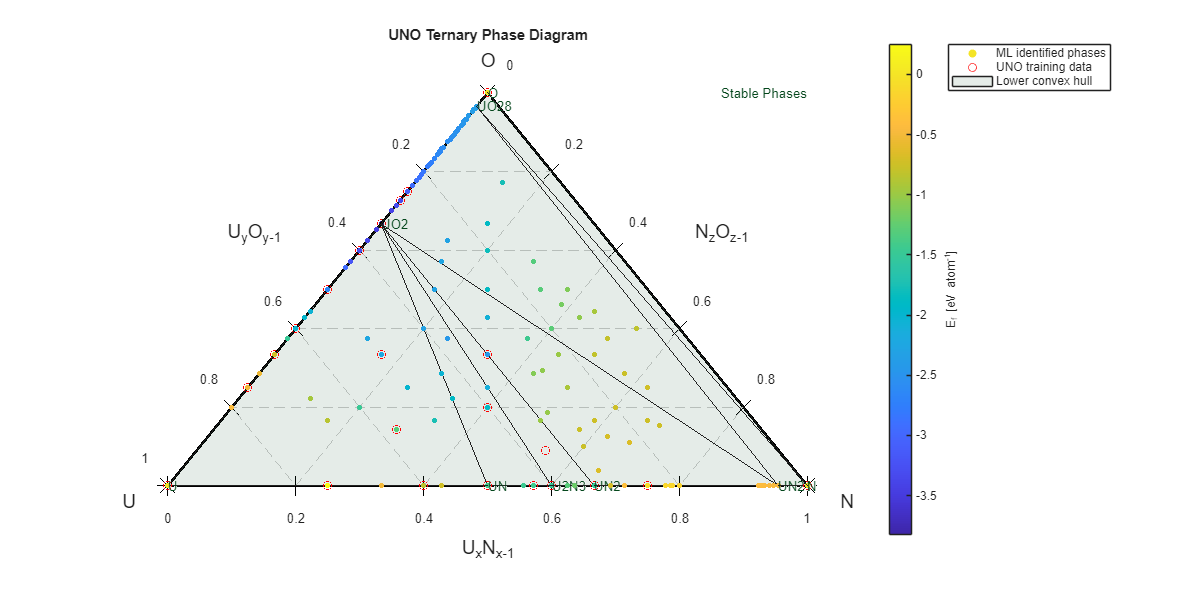

Stable Phases identified:
                  Ef_eV       
            __________________

    U2N3      -1.5127065652061
    UN       -1.41583815017175
    UN2        -1.495191535229
    UN21    -0.466678456193737
    UO2       -3.8192987939272
    UO28     -2.34277809006695
    U                        0
    N                        0
    O                        0

Metastable Phases identified:
                   Ef_eV       
             __________________

    U2O25      -2.4710637489954
    U2O27     -2.46028077254871
    U2O3      -3.32372922653689
    U2O49     -2.35937514565338
    U3N4      -1.43483207233915
    U3O4      -3.19075439359362
    U3O8 

results.spid = stable_pahse_ids;
results.mspid = metastable_phase_ids;
results.u = u;
results.v = v;
results.k = k;

% need to fix learning type error and graph labeling as axes are in the
% wrng order and still hardcoded at UNO

ternary_stable_phase_plotting(clean,results,non_CH_results,non_CH_data,userCom.composition,...
                                  0,... 3d view 
                                  1,... vu-vec
                                  1, ... stab.ph
                                  userCom.plotTitle ...
                                  )

toc

Elapsed time is 1.864471 seconds.
